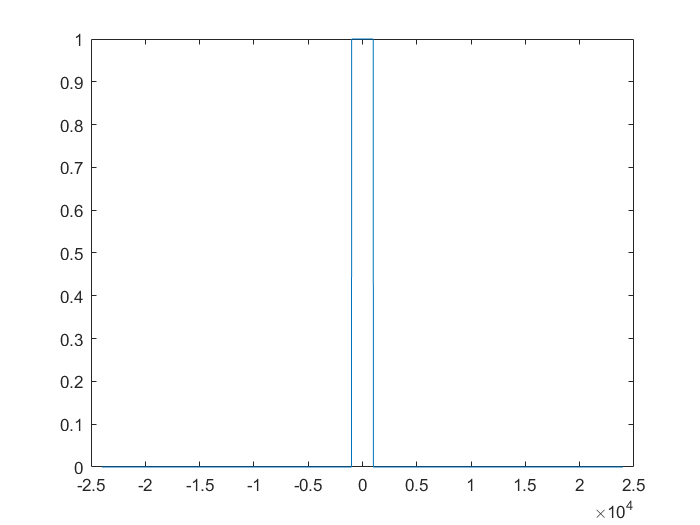

[audio,fs]=audioread('Audio_1.wav');
audio=(audio(:,1))';
time=0: 1/fs : (length(audio)-1)/fs;
omega=linspace(-fs/2,fs/2,length(audio));
FFT_audio=fftshift(fft(audio));
magnitude_audio=abs(FFT_audio);
phase_audio=angle(FFT_audio);


omega_low=1000;
omega_high=3000;

% low_pass_filter=(abs(omega)<=omega_low).*1;
 high_pass_filte=(abs(omega)>=omega_high).*1;

low_pass_filter=ctstep(omega+omega_low)-ctstep(omega-omega_low);
high_pass_filter=ones(1,length(omega))-(ctstep(omega+omega_high)-ctstep(omega-omega_high));

low_pass_magnitude=magnitude_audio.*low_pass_filter;
high_pass_magnitude=magnitude_audio.*high_pass_filter;

FFT_audio_low_filter=low_pass_magnitude.*exp(1i*phase_audio);
FFT_audio_high_filter=high_pass_magnitude.*exp(1i*phase_audio);

audio_low_filter=real(ifft(ifftshift(FFT_audio_low_filter)));
audio_high_filter=real(ifft(ifftshift(FFT_audio_high_filter)));

figure
plot(omega,low_pass_filter)

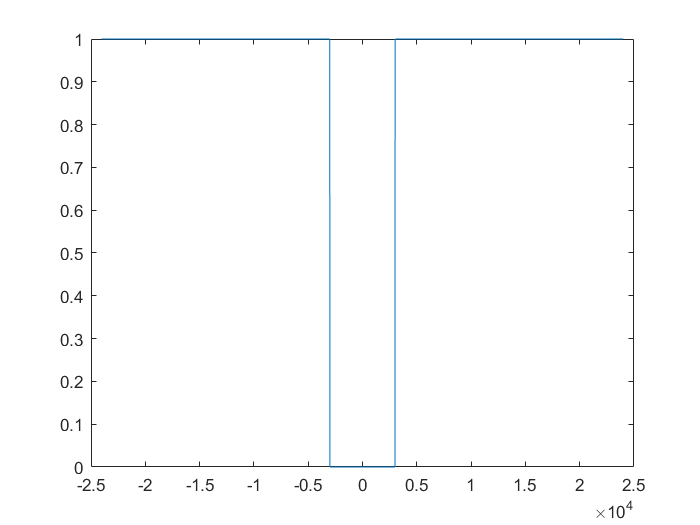

figure
plot(omega,high_pass_filter)

figure
plot(omega,high_pass_filte)